%% Task 4(b) - Validation SSE using polynomial models
clear; clc; close all;

%% Load data from Task 3
data = [
    0.5 480000; 2.0 1850000; 3.0 2100000;
    4.0 1900000; 4.5 3200000; 6.0 1750000;
    7.0 1850000; 9.0 1300000; 10.0 1450000;
    11.0 1400000; 12.0 1150000; 13.0 1100000;
    18.0 1200000; 17.0 1150000; 18.0 950000;
    16.0 1050000; 22.0 900000; 20.0 1200000;
    19.0 1300000; 9.0 1250000; 20.0 1000000;
    22.0 880000; 32.0 820000; 30.0 870000;
    50.0 780000; 35.0 1200000; 40.0 1250000;
    65.0 850000; 10.0 1900000; 8.0 1800000
];

d = data(:,1);   % distance from CBD
y = data(:,2);   % median house price

%% Set up polynomial orders and repeated random splits
orders = 0:20;          % polynomial orders from 0 to 20
numRuns = 100;          % repeat random train/validation split 100 times
trainRatio = 0.70;      % use 70% for fitting
n = length(d);
numTrain = round(trainRatio * n);

avgValidationSSE = zeros(size(orders));

%% Repeat the order sweep
for k = 1:length(orders)

    order = orders(k);
    sseRuns = zeros(numRuns, 1);

    for r = 1:numRuns

        %% Randomly split data into training and validation sets
        idx = randperm(n);

        trainIdx = idx(1:numTrain);
        valIdx = idx(numTrain+1:end);

        dTrain = d(trainIdx);
        yTrain = y(trainIdx);

        dVal = d(valIdx);
        yVal = y(valIdx);

        %% Fit polynomial using training data only
        % Important: validation data is NOT used here
        p = polyfit(dTrain, yTrain, order);

        %% Predict on validation data
        % Validation data is only used after fitting
        yValPred = polyval(p, dVal);

        %% Compute validation SSE
        sseRuns(r) = sum((yVal - yValPred).^2);
    end

    %% Average validation SSE for this polynomial order
    avgValidationSSE(k) = mean(sseRuns);
end

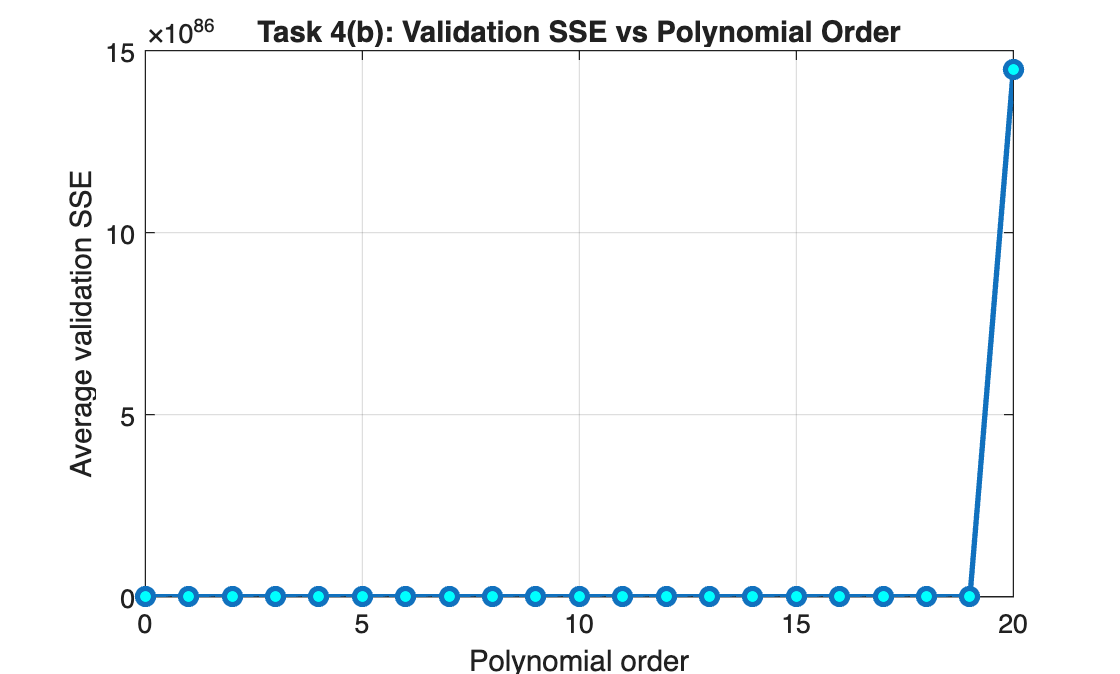


%% Plot validation SSE against polynomial order
figure;
plot(orders, avgValidationSSE, 'o-', ...
    'LineWidth', 2, ...
    'MarkerFaceColor', 'cyan');

xlabel('Polynomial order');
ylabel('Average validation SSE');
title('Task 4(b): Validation SSE vs Polynomial Order');
grid on;

%% Task 4(b) - Core code snippet

orders = 0:20;          % polynomial orders from 0 to 20
numRuns = 100;          % repeat random train/validation split
trainRatio = 0.70;      % 70% training, 30% validation

n = length(d);
numTrain = round(trainRatio * n);

avgValidationSSE = zeros(size(orders));

for k = 1:length(orders)

    order = orders(k);
    sseRuns = zeros(numRuns, 1);

    for r = 1:numRuns

        % Randomly split data into training and validation sets
        idx = randperm(n);

        trainIdx = idx(1:numTrain);
        valIdx = idx(numTrain+1:end);

        dTrain = d(trainIdx);
        yTrain = y(trainIdx);

        dVal = d(valIdx);
        yVal = y(valIdx);

        % Fit polynomial using training data only
        p = polyfit(dTrain, yTrain, order);

        % Predict on validation data
        yValPred = polyval(p, dVal);

        % Compute validation SSE
        sseRuns(r) = sum((yVal - yValPred).^2);
    end

    % Average SSE across random runs
    avgValidationSSE(k) = mean(sseRuns);
end

% Plot validation SSE against polynomial order
figure;
plot(orders, avgValidationSSE, 'o-', ...
    'LineWidth', 2, ...
    'MarkerFaceColor', 'cyan');

xlabel('Polynomial order');
ylabel('Average validation SSE');
title('Task 4(b): Validation SSE vs Polynomial Order');
grid on;